slaveAVGPTPStack1 = readtable('AVGSlave_PTPStack-1.csv', 'HeaderLines', 1);
slaveAVGPTPStack2 = readtable('AVGSlave_PTPStack-2.csv', 'HeaderLines', 1);
slaveAVGPTPStack3 = readtable('AVGSlave_PTPStack-3.csv', 'HeaderLines', 1);
slaveAVGPTPStack4 = readtable('AVGSlave_PTPStack-4.csv', 'HeaderLines', 1);
slaveAVGClockServo = readtable('AVGSlave_ClockServo.csv', 'HeaderLines', 1);

slaveFTAPTPStack1 = readtable('FTASlave_PTPStack-1.csv', 'HeaderLines', 1);
slaveFTAPTPStack2 = readtable('FTASlave_PTPStack-2.csv', 'HeaderLines', 1);
slaveFTAPTPStack3 = readtable('FTASlave_PTPStack-3.csv', 'HeaderLines', 1);
slaveFTAPTPStack4 = readtable('FTASlave_PTPStack-4.csv', 'HeaderLines', 1);
slaveFTAClockServo = readtable('FTASlave_ClockServo.csv', 'HeaderLines', 1);

phase1 = [59, 61];
phase2 = [89, 91];
phase3 = [119, 121];
phase4 = [149, 151];


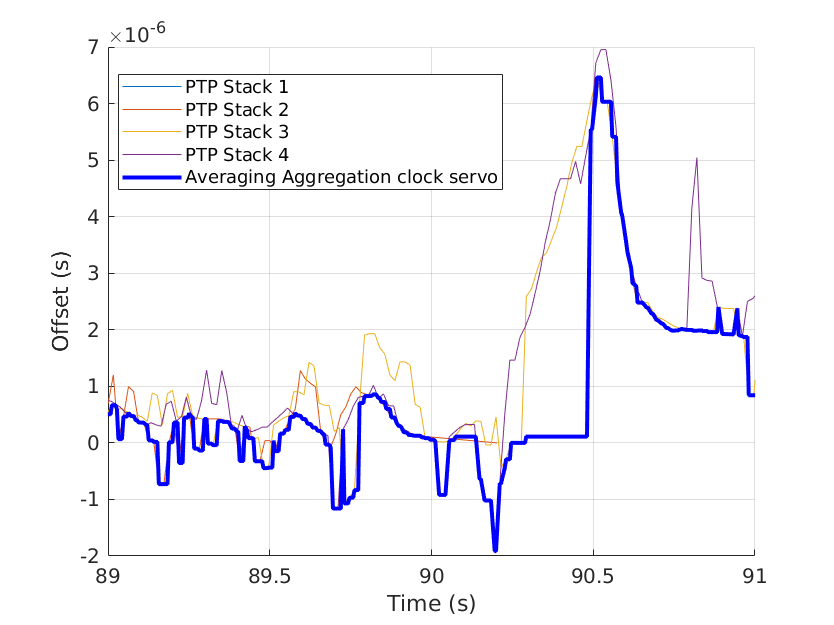

f1_cs = figure;
hold on;

plot(slaveAVGPTPStack1.Var1, slaveAVGPTPStack1.Var2);
plot(slaveAVGPTPStack2.Var1, slaveAVGPTPStack2.Var2);
plot(slaveAVGPTPStack3.Var1, slaveAVGPTPStack3.Var2);
plot(slaveAVGPTPStack4.Var1, slaveAVGPTPStack4.Var2);
plot(slaveAVGClockServo.Var1, slaveAVGClockServo.Var2,'Color','b','Linewidth', 2);

legend("PTP Stack 1", "PTP Stack 2", "PTP Stack 3", "PTP Stack 4", "Averaging Aggregation clock servo", 'Location', 'Best');
xlabel("Time (s)");
ylabel("Offset (s)");
xlim(phase2);
grid on;
hold off;

saveas(f1_cs,'ptpStackAggregationAVG', 'svg');

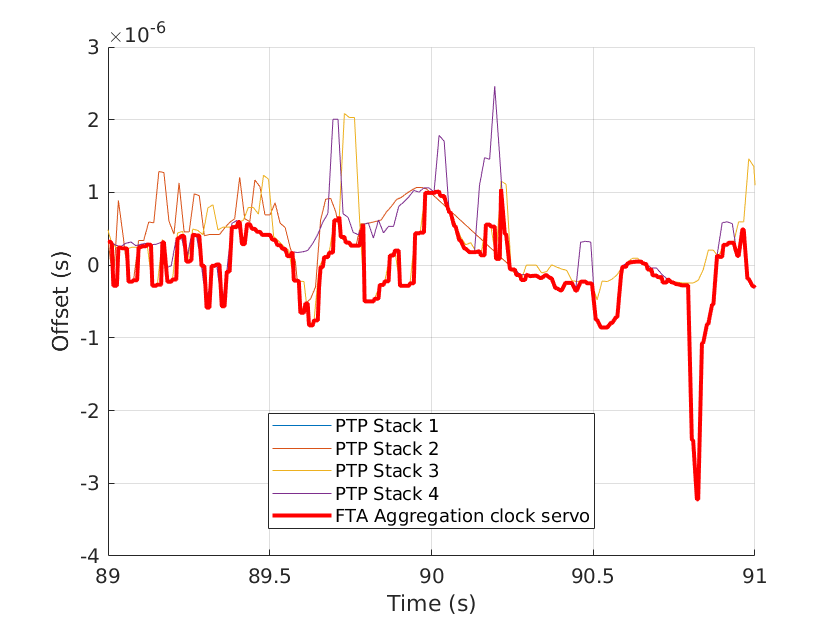

f2_cs = figure;
hold on;

plot(slaveFTAPTPStack1.Var1, slaveFTAPTPStack1.Var2);
plot(slaveFTAPTPStack2.Var1, slaveFTAPTPStack2.Var2);
plot(slaveFTAPTPStack3.Var1, slaveFTAPTPStack3.Var2);
plot(slaveFTAPTPStack4.Var1, slaveFTAPTPStack4.Var2);
plot(slaveFTAClockServo.Var1, slaveFTAClockServo.Var2,'Color','r','Linewidth', 2);

legend("PTP Stack 1", "PTP Stack 2", "PTP Stack 3", "PTP Stack 4", "FTA Aggregation clock servo", 'Location', 'Best');
xlabel("Time (s)");
ylabel("Offset (s)");
% ylim([-5e-6 5e-6])
xlim(phase2);
grid on;
hold off;

saveas(f2_cs,'ptpStackAggregationFTA', 'svg');